## Initialize the P, T and b for the Square manually

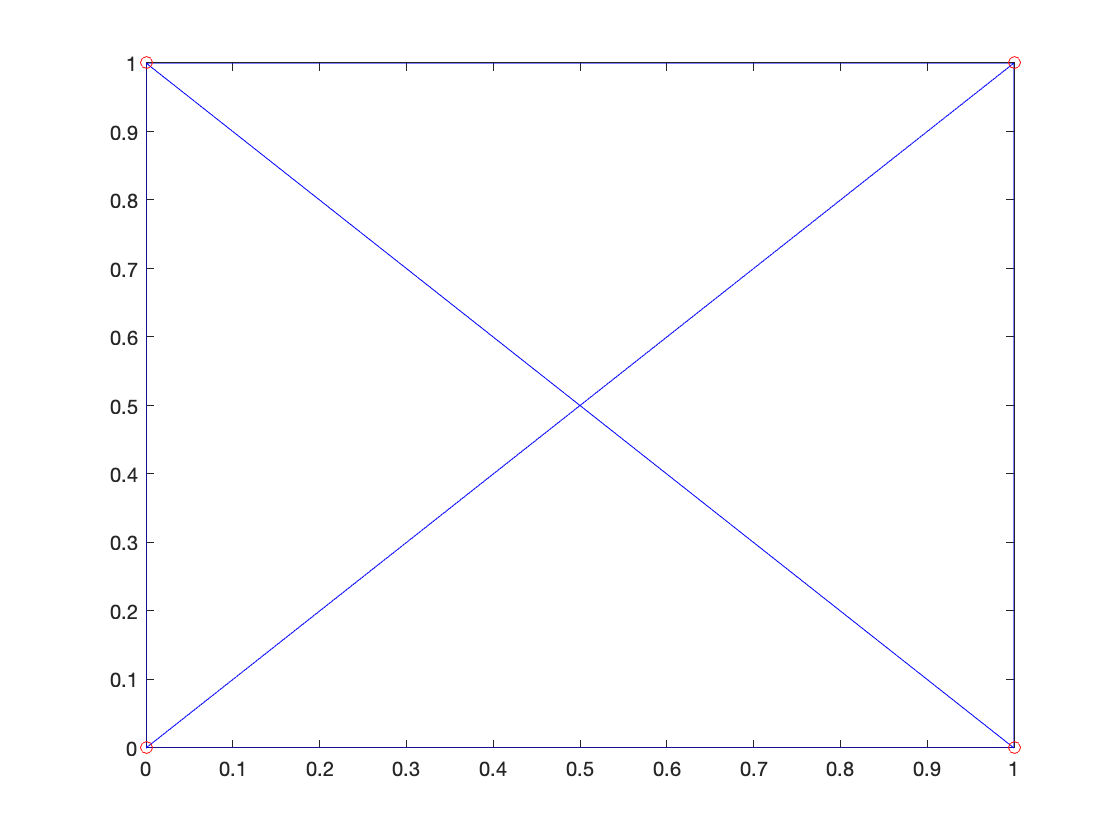

P = [0 0;
     1 0;
     1 1;
     0 1;
     1/2 1/2];
 
T = [1 2 5;
     2 3 5;
     3 4 5;
     4 1 5];

b = [0;
     0;
     0;
     0;
     1];


figure 
vistriang(P, T, b)

## refine the mesh and then visualize

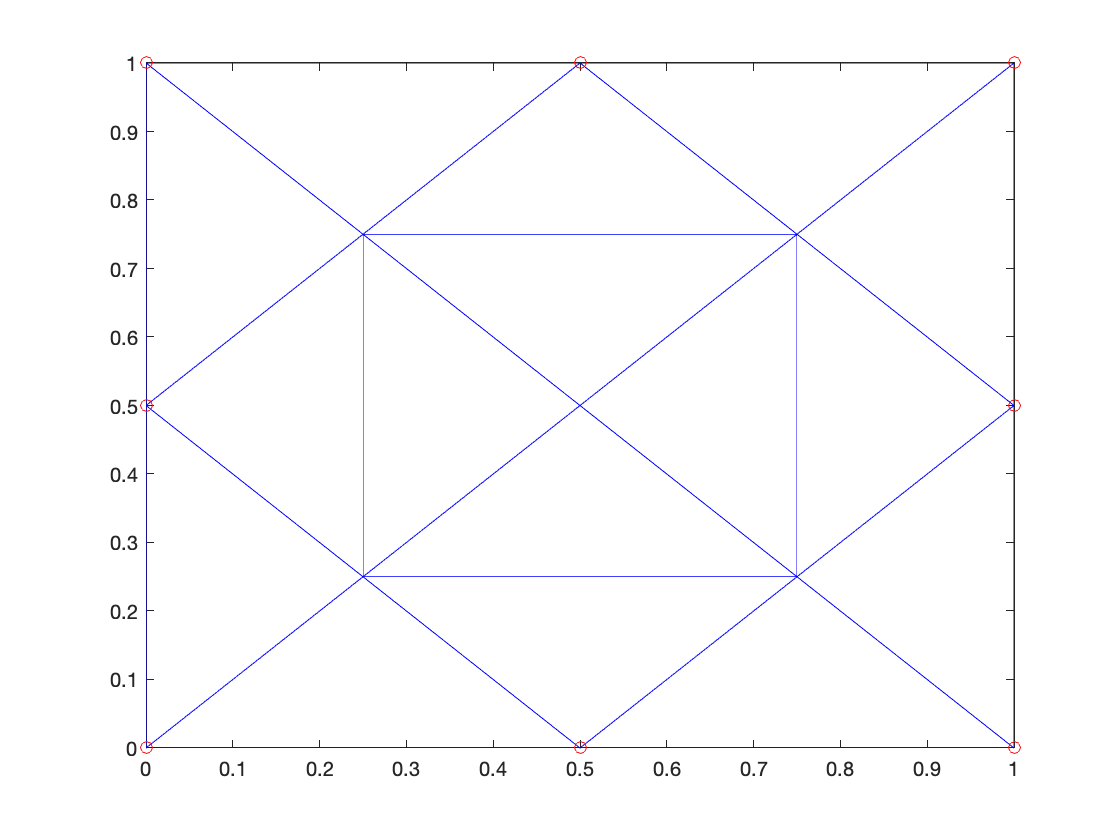

figure
[PP, TT, bb] = refine(P, T, b);
vistriang(PP, TT, bb)

## Definition of Functions Part

Visualization of the mesh when the Point list **P**, Element list **T**, and boundary category list **b** are given.

Interior node b=1 

Boundary node with Dirichlet boundary condition  b=0 - RED

Boundary node Neumann boundary condition b=2 - GREEN

function vistriang(P, T, b)
    triplot(T, P(:, 1), P(:, 2));
    hold on;
    for i = 1 : length(b)
        if b(i) == 0
            plot(P(i,1), P(i,2), "ro");
        elseif b(i) == 2
            plot(P(i,1), P(i,2), "go");
        end
    end
end

Refinement function

function [PP, TT, bb] = refine(P, T, b)

    %% Getting Edge lists
    E = {};

    for i = 1:size(P, 1)
        E{end + 1} = {};
    end

    % Iteration over triangles
    for i = 1:size(T, 1)
        % Iteration over triangle points
        for j = 1:3
            ea = T(i, j);
            eb = T(i, mod(j, 3) + 1);

            if ea > eb
                tmp = ea;
                ea = eb;
                eb = tmp;
            end

            E{ea}{end + 1} = eb;
        end

    end

    for i = 1:size(E, 2)
        E{i} = cell2mat(E{i});
        E{i} = unique(E{i});
        E{i} = sort(E{i});
    end

    %% Getting  PP and bb
    PP = [P];
    bb = [b];
    L = {};

    for i = 1:size(E, 2)

        for j = 1:length(E{i})
            pt1 = P(i, :);
            pt2 = P(E{i}(j), :);
            midpt = (pt1 + pt2) ./ 2;

            PP = [PP; midpt];
            L{i, j} = length(PP);

            if b(i) == 0 && b(E{i}(j)) == 0
                bb(L{i, j}) = 0;
            else
                bb(L{i, j}) = 1;
            end

        end

    end

    %% Getting TT
    TT = [T];

    m = [0, 0, 0];

    for i = 1:length(T)

        for j = 1:3
            % finding index
            ea = T(i, j);
            eb = T(i, mod(j, 3) + 1);

            if ea > eb
                % Shall i skip here?
                tmp = ea;
                ea = eb;
                eb = tmp;
            end

            k1 = ea;
            k2 = find(E{ea} == eb);
            m(j) = L{k1, k2};

        end

        TT(4 * i - 3:4 * i, :) = [
                            T(i, 1), m(1), m(3);
                            m(1), T(i, 2), m(2);
                            m(3), m(2), T(i, 3);
                            m(1), m(2), m(3);
                            ];

    end

end

## Reference

Solution to the assignment 3 by [Iaroslav Petrov](https://www.icorsi.ch/user/view.php?id=24152&course=10054) [Srihari Sridharan](https://www.icorsi.ch/user/view.php?id=39763&course=10054) [Jingfeng Rong](https://www.icorsi.ch/user/view.php?id=39942&course=10054)